clear;
clear clc;
% PHYS 434
% LAB 7 & 8
% Jin Kyoung Lee

% Importing data
% Signal dataset (Higgs)
h5disp("LAB/Higgs_data/Sample_low_pt/higgs_100000_pt_250_500.h5");

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higgsData = h5read("LAB/Higgs_data/Sample_low_pt/higgs_100000_pt_250_500.h5","/higgs_100000_pt_250_500");

% Background dataset (QCD)
h5disp("LAB/Higgs_data/Sample_low_pt/qcd_100000_pt_250_500.h5");

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


qcdData = h5read("LAB/Higgs_data/Sample_low_pt/qcd_100000_pt_250_500.h5","/qcd_100000_pt_250_500");

## 1

N0_qcd = 20000 % Background: Poisson distribution with lambda = 20000

N0_qcd = 20000

N0_higgs = 100 % Signal: Poisson distribution with lambda = 100

N0_higgs = 100

N_tot = N0_qcd + N0_higgs

N_tot = 20100

significance = N0_higgs / sqrt(N0_qcd)

significance = 0.7071

% If we integrate the distribution of background (QCD) from 20100 to the
% right end of the probability distribution (i.e. find the area under the
% probability distribution curve for background with lower bound of 20100
% and upper bound of ........ ), then we would get the probability of 0.707.
% This probability is corresponding to N_Higgs/√(N_QCD) = 100/√20000, which
% is the significance for N_total.

## 2

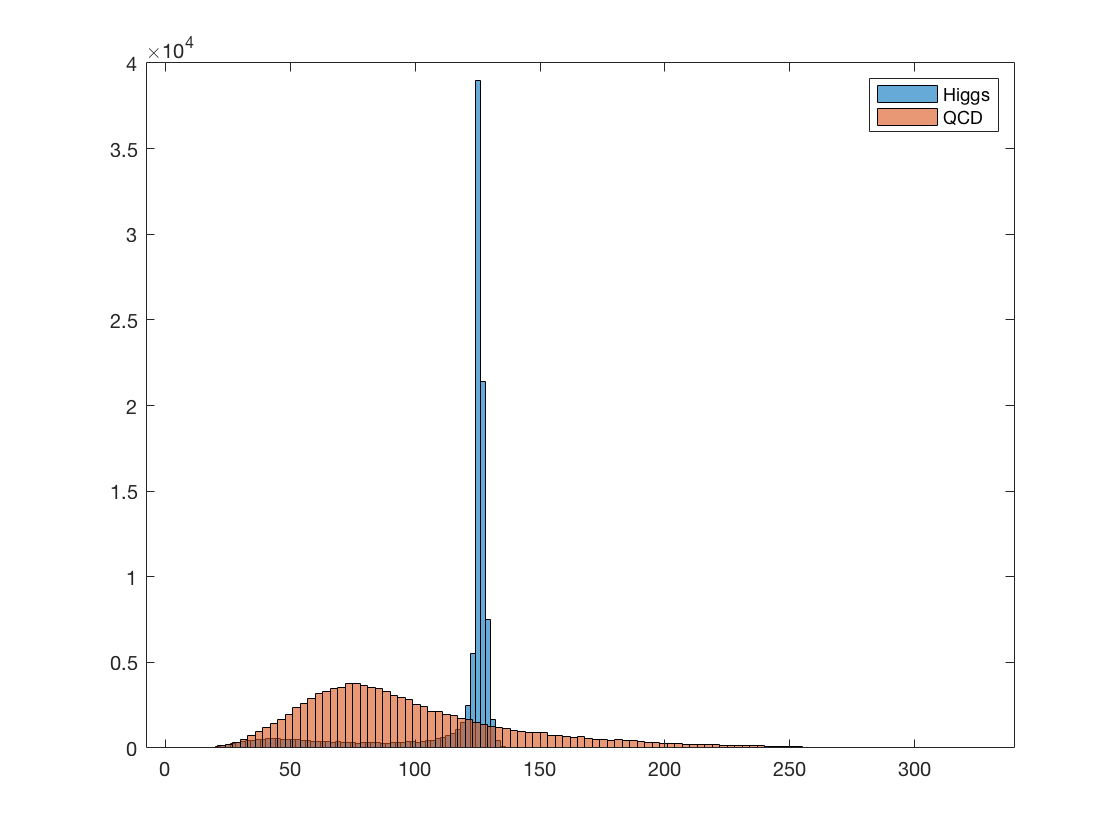

% Histogram for the feature variable: mass
% Higgs
massHiggs = higgsData(4,1:100000);
histogram(massHiggs,'DisplayStyle','bar')
hold on
% QCD
massQCD = qcdData(4,1:100000);
histogram(massQCD,'DisplayStyle','bar')
legend ("Higgs","QCD")
hold off

## Loop QCD (cut 0 to 140)

N_qcd_all_range = 100000;
% Mass cuts = 0 to 140
cutsMax1 = 140;
for i = 1:100000
    cuts(i) = massQCD(i);
    if (cuts(i) <= cutsMax1)
        massQCDCuts1 = cuts(cuts <= cutsMax1);
    end
end

## selected range1

N_qcd_select_range1 = length(massQCDCuts1)

N_qcd_select_range1 = 84586

N_qcd_selectedLambda1 = N0_qcd * (N_qcd_select_range1 / N_qcd_all_range)

N_qcd_selectedLambda1 = 1.6917e+04

## Loop QCD (cut 0 to 100)

cutsMax2 = 100;
for i = 1:100000
    cuts(i) = massQCD(i);
    if (cuts(i) <= cutsMax2)
        massQCDCuts2 = cuts(cuts <= cutsMax2);
    end
end

## selected range2

N_qcd_select_range2 = length(massQCDCuts2)

N_qcd_select_range2 = 61799

N_qcd_selectedLambda2 = N0_qcd * (N_qcd_select_range2 / N_qcd_all_range)

N_qcd_selectedLambda2 = 1.2360e+04

## Loop Higgs (cut 0 to 140)

N_higgs_all_range = 100000;
% Mass cuts = 0 to 140
for i = 1:100000
    cuts(i) = massHiggs(i);
    if (cuts(i) <= cutsMax1)
        massHiggsCuts1 = cuts(cuts <= cutsMax1);
    end
end

## selected range1

N_higgs_select_range1 = length(massHiggsCuts1)

N_higgs_select_range1 = 99998

N_higgs_selectedLambda1 = N0_higgs * (N_higgs_select_range1 / N_higgs_all_range)

N_higgs_selectedLambda1 = 99.9980

## Loop Higgs (cut 0 to 100)

% Mass cuts = 0 to 100
for i = 1:100000
    cuts(i) = massHiggs(i);
    if (cuts(i) <= cutsMax2)
        massHiggsCuts2 = cuts(cuts <= cutsMax2);
    end
end

## selected range2

N_higgs_select_range2 = length(massHiggsCuts2)

N_higgs_select_range2 = 15053

N_higgs_selectedLambda2 = N0_higgs * (N_higgs_select_range2 / N_higgs_all_range)

N_higgs_selectedLambda2 = 15.0530

## Significance

% for mass cut from 0 to 140
N_higgs_selectedLambda1 / sqrt(N_qcd_selectedLambda1)

ans = 0.7688

% for mass cut from 0 to 100
N_higgs_selectedLambda2 / sqrt(N_qcd_selectedLambda2)

ans = 0.1354

% It has shown from the above results, mass cut from 0 to 140 gives higher
% significance. (0.7688)

## 3

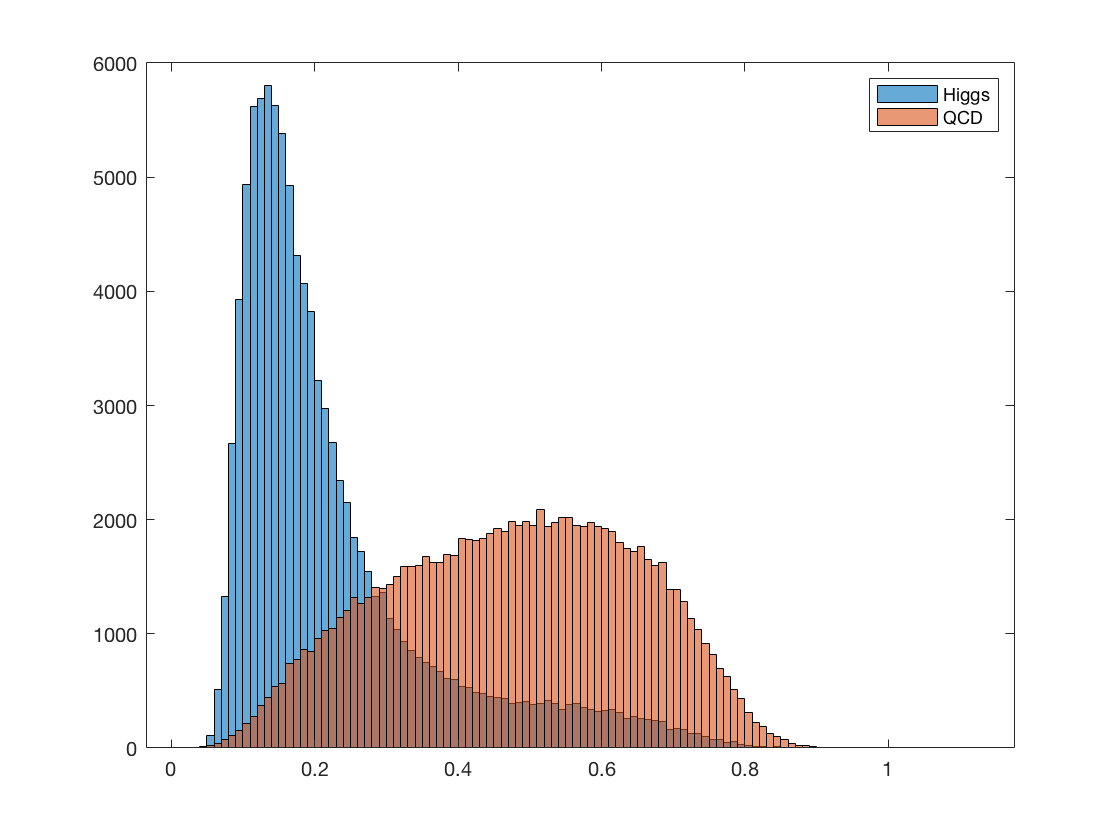

% Histogram for the feature variable: t3
% Higgs
t3Higgs = higgsData(11,1:100000);
histogram(t3Higgs,'DisplayStyle','bar')
hold on
% QCD
t3QCD = qcdData(11,1:100000);
histogram(t3QCD,'DisplayStyle','bar')
legend ("Higgs","QCD")
hold off

% From the histogram plot, it is observed that t3 is as discriminative as
% mass feature.

## 4

## Loop QCD (cut 0 to 0.3)

% t3 cuts = 0 to 0.3
cuts2Max1 = 0.3;
for i = 1:100000
    cuts2(i) = t3QCD(i);
    if (cuts2(i) <= cuts2Max1)
        t3QCDCuts1 = cuts2(cuts2 <= cuts2Max1);
    end
end

## selected range1

N_qcd_select_range1_t3 = length(t3QCDCuts1)

N_qcd_select_range1_t3 = 18139

N_qcd_selectedLambda1_t3 = N0_qcd * (N_qcd_select_range1_t3 / N_qcd_all_range)

N_qcd_selectedLambda1_t3 = 3.6278e+03

## Loop QCD (cut 0.3 to 1)

% t3 cuts = 0.3 to 1
cuts2Min2 = 0.3;
cuts2Max2 = 1;
for i = 1:100000
    cuts2(i) = t3QCD(i);
    if (cuts2(i) >= cuts2Min2) && (cuts2(i) <= cuts2Max2)
        t3QCDCuts2 = cuts2((cuts2 >= cuts2Min2) & (cuts2 <= cuts2Max2));
    end
end

## selected range2

N_qcd_select_range2_t3 = length(t3QCDCuts2)

N_qcd_select_range2_t3 = 81857

N_qcd_selectedLambda2_t3 = N0_qcd * (N_qcd_select_range2_t3 / N_qcd_all_range)

N_qcd_selectedLambda2_t3 = 1.6371e+04

## Loop QCD (cut 0 to 0.8)

% t3 cuts = 0 to 0.8
cuts2Max3 = 0.8;
for i = 1:100000
    cuts2(i) = t3QCD(i);
    if (cuts2(i) <= cuts2Max3)
        t3QCDCuts3 = cuts2(cuts2 <= cuts2Max3);
    end
end

## selected range3

N_qcd_select_range3_t3 = length(t3QCDCuts3)

N_qcd_select_range3_t3 = 98857

N_qcd_selectedLambda3_t3 = N0_qcd * (N_qcd_select_range3_t3 / N_qcd_all_range)

N_qcd_selectedLambda3_t3 = 1.9771e+04

## Loop Higgs (cut 0 to 0.3)

% t3 cuts = 0 to 0.3
for i = 1:100000
    cuts2(i) = t3Higgs(i);
    if (cuts2(i) <= cuts2Max1)
        t3HiggsCuts1 = cuts2(cuts2 <= cuts2Max1);
    end
end

## selected range1

N_higgs_select_range1_t3 = length(t3HiggsCuts1)

N_higgs_select_range1_t3 = 79920

N_higgs_selectedLambda1_t3 = N0_higgs * (N_higgs_select_range1_t3 / N_higgs_all_range)

N_higgs_selectedLambda1_t3 = 79.9200

## Loop Higgs (cut 0.3 to 1)

% t2 cuts = 0.3 to 1
for i = 1:100000
    cuts2(i) = t3Higgs(i);
    if (cuts2(i) >= cuts2Min2) && (cuts2(i) <= cuts2Max2)
        t3HiggsCuts2 = cuts2((cuts2 >= cuts2Min2) & (cuts2 <= cuts2Max2));
    end
end

## selected range2

N_higgs_select_range2_t3 = length(t3HiggsCuts2)

N_higgs_select_range2_t3 = 20079

N_higgs_selectedLambda2_t3 = N0_higgs * (N_higgs_select_range2_t3 / N_higgs_all_range)

N_higgs_selectedLambda2_t3 = 20.0790

## Loop Higgs (cut 0 to 0.8)

% t3 cuts = 0 to 0.8
for i = 1:100000
    cuts2(i) = t3Higgs(i);
    if (cuts2(i) <= cuts2Max3)
        t3HiggsCuts3 = cuts2(cuts2 <= cuts2Max3);
    end
end

## selected range3

N_higgs_select_range3_t3 = length(t3HiggsCuts3)

N_higgs_select_range3_t3 = 99908

N_higgs_selectedLambda3_t3 = N0_higgs * (N_higgs_select_range3_t3 / N_higgs_all_range)

N_higgs_selectedLambda3_t3 = 99.9080

## Significance (t3)

% for t3 cut from 0 to 0.3
N_higgs_selectedLambda1_t3 / sqrt(N_qcd_selectedLambda1_t3)

ans = 1.3269

% for t3 cut from 0.3 to 1
N_higgs_selectedLambda2_t3 / sqrt(N_qcd_selectedLambda2_t3)

ans = 0.1569

% for t2 cut from 0 to 0.8
N_higgs_selectedLambda3_t3 / sqrt(N_qcd_selectedLambda3_t3)

ans = 0.7105

% It has shown from the above results, t3 cut from 0 to 0.8 gives higher
% significance. (0.7105)

## Pseudo-experiment data analysis

% Importing data
% High Luminosity
h5disp("LAB/Higgs_data/Sample_low_pt/data_highLumi_pt_250_500.h5")

HDF5 data_highLumi_pt_250_500.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attributes

highLumiData = h5read("LAB/Higgs_data/Sample_low_pt/data_highLumi_pt_250_500.h5","/data/block0_values");

% Low Luminosity
h5disp("LAB/Higgs_data/Sample_low_pt/data_lowLumi_pt_250_500.h5")

HDF5 data_lowLumi_pt_250_500.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attributes:

lowLumiData = h5read("LAB/Higgs_data/Sample_low_pt/data_LowLumi_pt_250_500.h5","/data/block0_values");

## 1. High luminosity data

massHighLumi = highLumiData(4,1:40344);
N_tot_new = N_qcd_selectedLambda1+N_higgs_selectedLambda1

N_tot_new = 1.7017e+04

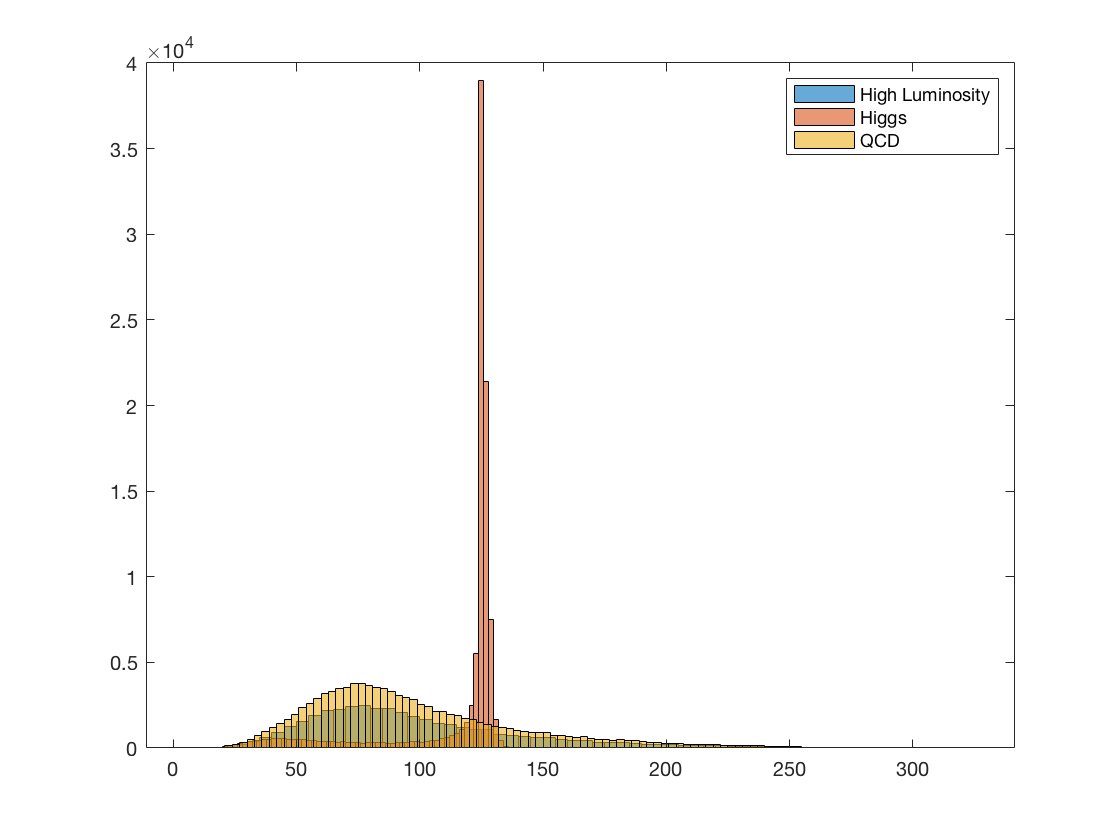

% Without event selection
histogram(massHighLumi,'DisplayStyle','bar')
hold on
histogram(massHiggs,'DisplayStyle','bar')
histogram(massQCD,'DisplayStyle','bar')
hold off
legend('High Luminosity','Higgs','QCD')

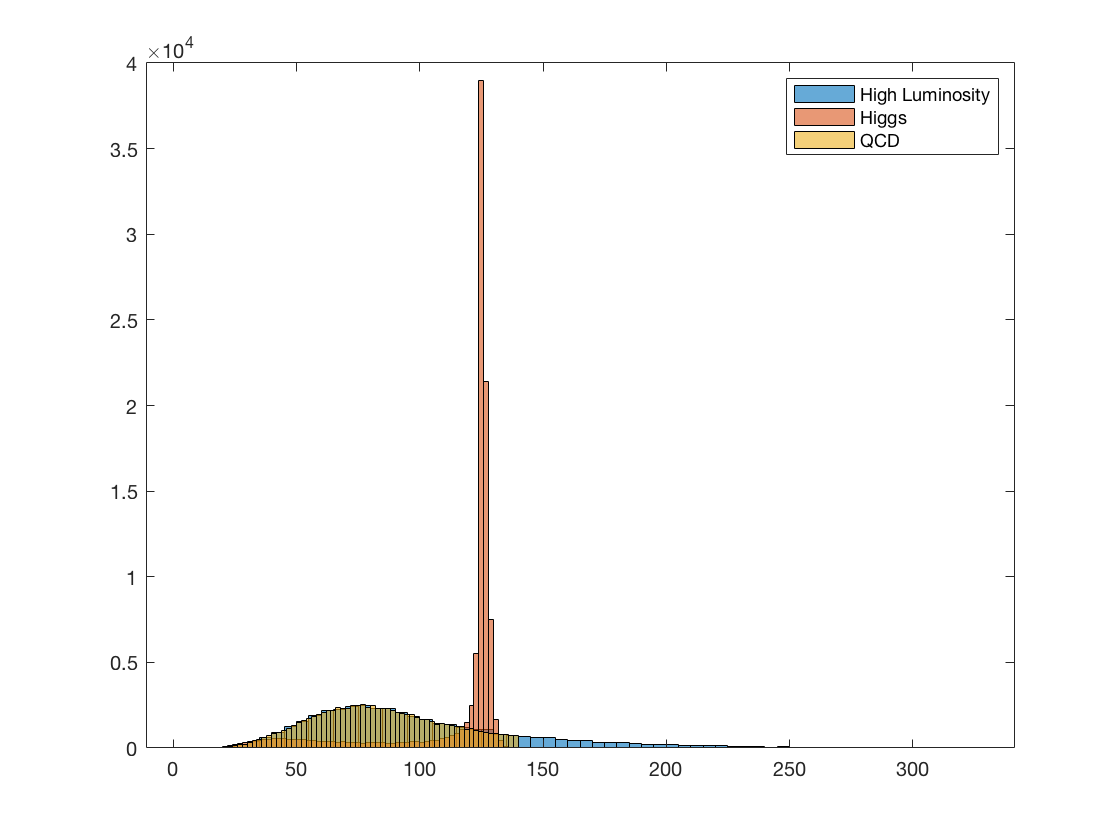

% With optimal event select
histogram(massHighLumi,'DisplayStyle','bar')
hold on
histogram(massHiggsCuts1,'DisplayStyle','bar')
histogram(massQCDCuts1,'DisplayStyle','bar')
hold off
legend('High Luminosity','Higgs','QCD')

% Mass cuts = 0 to 140
for i = 1:40344
    %cuts(i) = highLumiData(i);
    cuts(i) = massHighLumi(i);
    if (cuts(i) <= cutsMax1)
        highLumiCuts1 = cuts(cuts <= cutsMax1);
    end
end

N_highLumi_select_range = length(highLumiCuts1)

N_highLumi_select_range = 93790

N_highLumi_selectedLambda = N0_qcd * (N_highLumi_select_range / N_qcd_all_range)

N_highLumi_selectedLambda = 18758

N_higgs_selectedLambda1 / sqrt(N_highLumi_selectedLambda)

ans = 0.7301

% Observed significance = 0.7301
% Expected significance (without sevent selection) = 0.7071
% Expected significance (with optimal event selection) = 0.7688

## 2. Low luminosity data

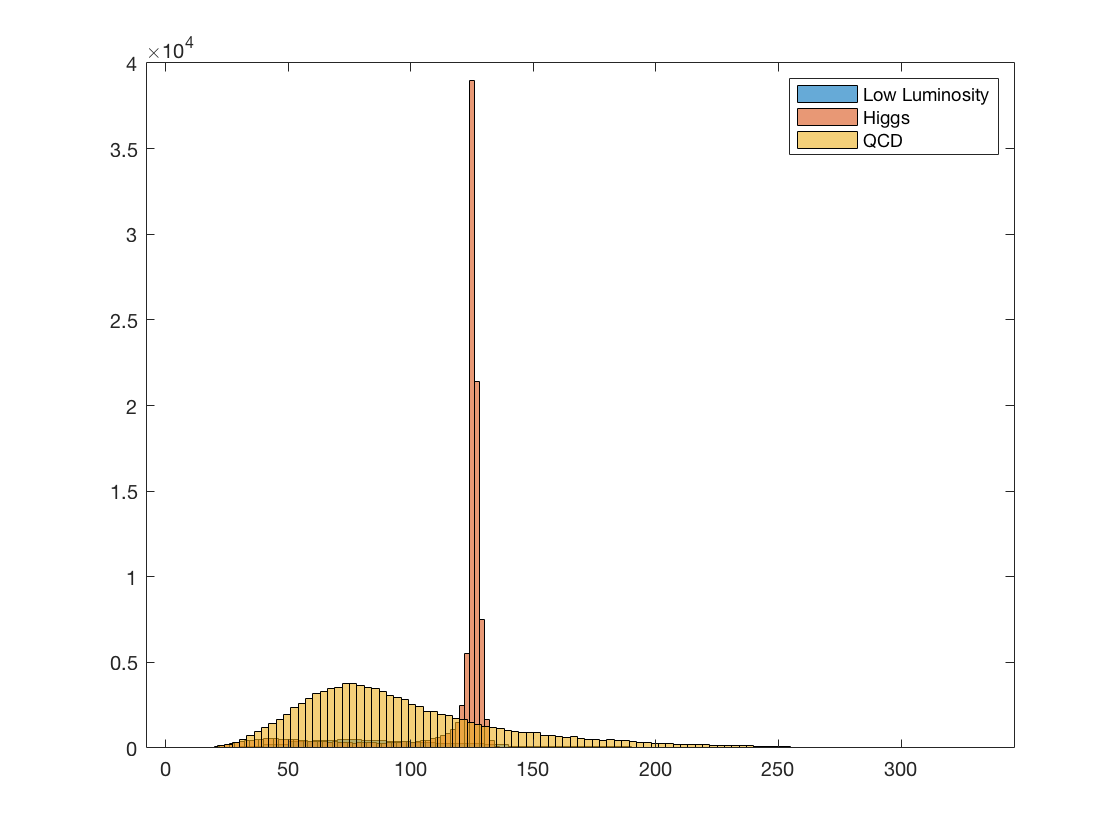

massLowLumi = lowLumiData(4,1:4060);
% Without event selection
histogram(massLowLumi,'DisplayStyle','bar')
hold on
histogram(massHiggs,'DisplayStyle','bar')
histogram(massQCD,'DisplayStyle','bar')
hold off
legend('Low Luminosity','Higgs','QCD')

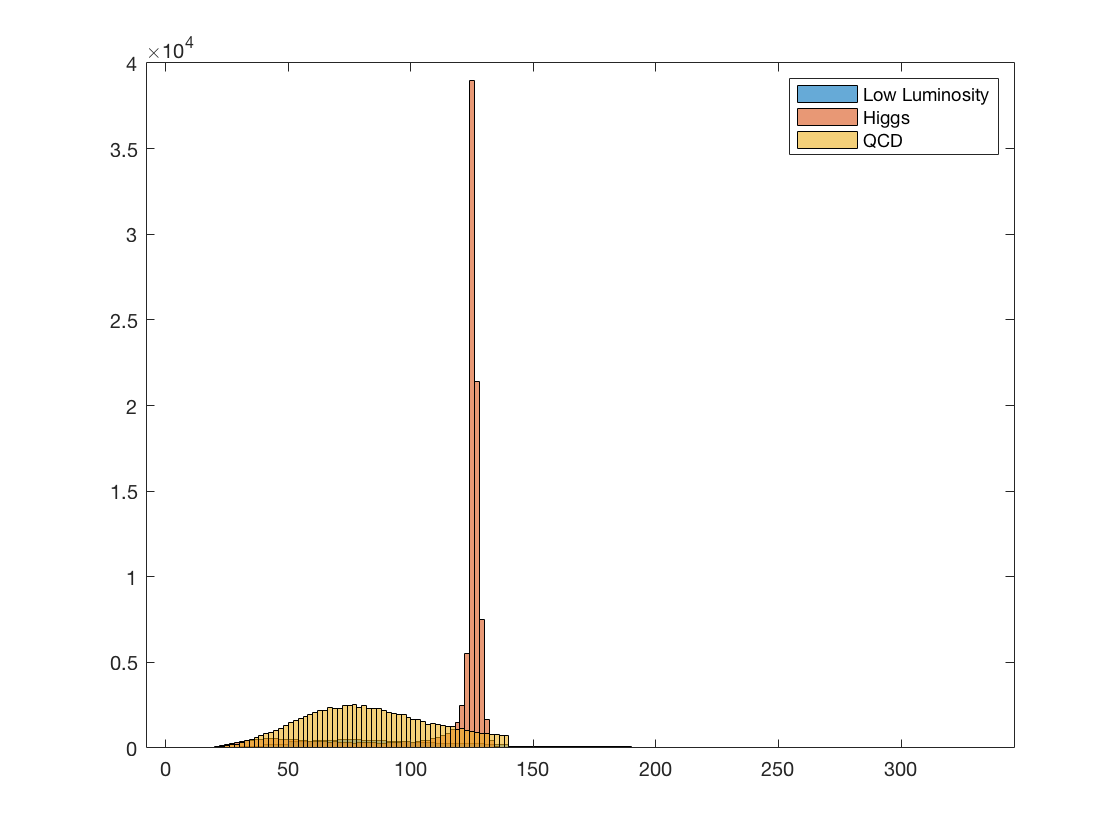

% With optimal event select
histogram(massLowLumi,'DisplayStyle','bar')
hold on
histogram(massHiggsCuts1,'DisplayStyle','bar')
histogram(massQCDCuts1,'DisplayStyle','bar')
hold off
legend('Low Luminosity','Higgs','QCD')

% Mass cuts = 0 to 140
for i = 1:4060
    %cuts(i) = lowLumiData(i);
    cuts_high(i) = massLowLumi(i);
    if (cuts_high(i) >= 0) && (cuts_high(i) <= cutsMax1)
        lowLumiCuts1 = cuts_high((cuts_high >= 0) & (cuts_high <= cutsMax1));
    end
end

N_lowLumi_select_range = length(lowLumiCuts1)

N_lowLumi_select_range = 3480

N_lowLumi_selectedLambda = N0_qcd * (N_lowLumi_select_range / N_qcd_all_range)

N_lowLumi_selectedLambda = 696

N_higgs_selectedLambda1 / sqrt(40344)

ans = 0.4979

% Observed significance = 0.7300
% Expected significance (without event selection) = 0.7071
% Expected significance (with optimal event selection) = 0.7688

## 95% confidence level of sinal yields